初始总能量: 78
Monte Carlo 步: 1


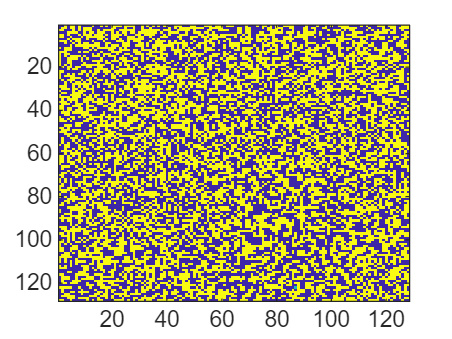

Monte Carlo 步: 2


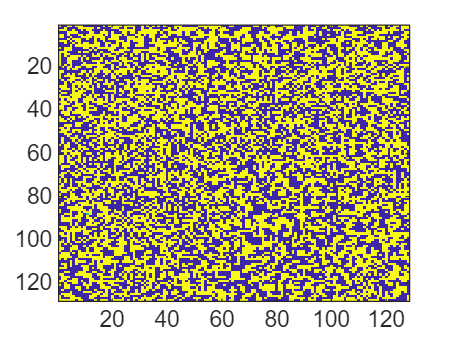

Monte Carlo 步: 4


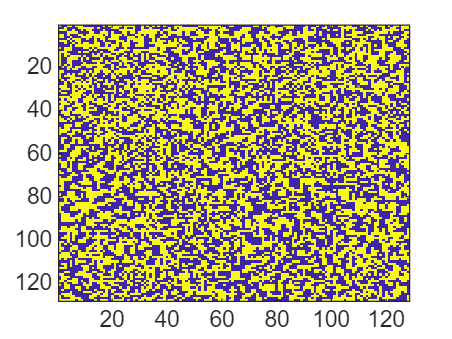

Monte Carlo 步: 8


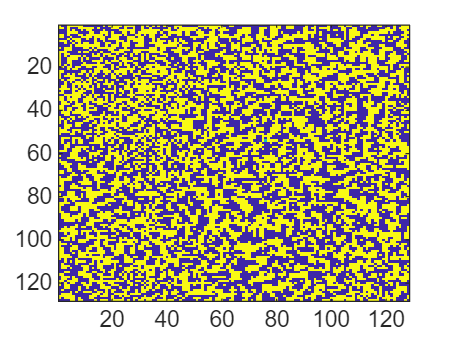

Monte Carlo 步: 16


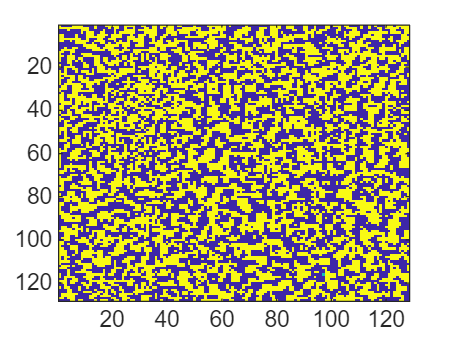

Monte Carlo 步: 32


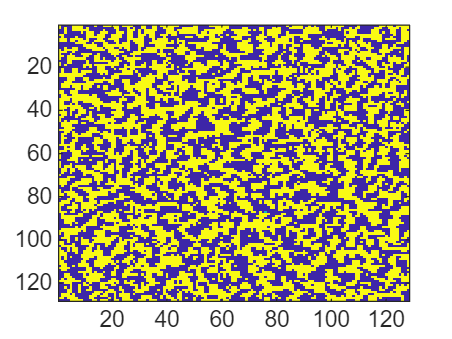

Monte Carlo 步: 64


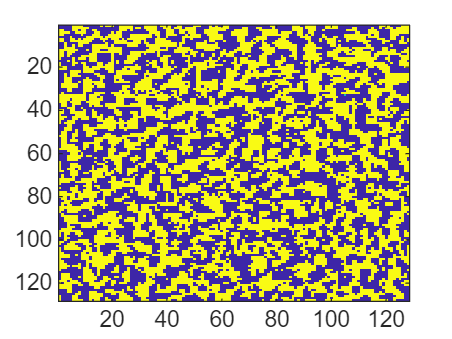

Monte Carlo 步: 128


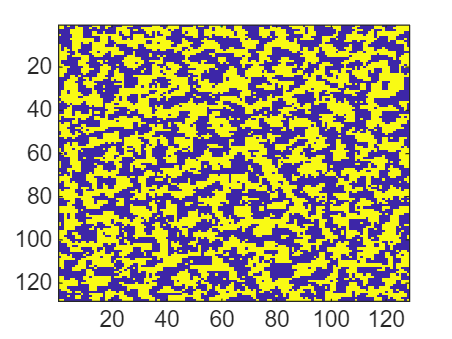

Monte Carlo 步: 256


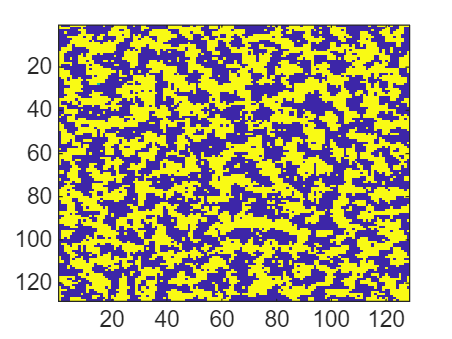

Monte Carlo 步: 512


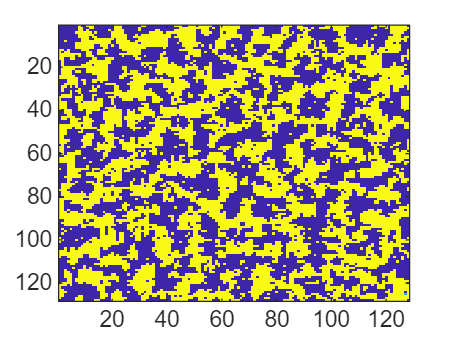

Monte Carlo 步: 1024


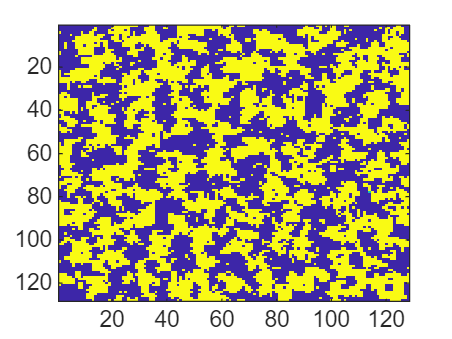

Monte Carlo 步: 2048


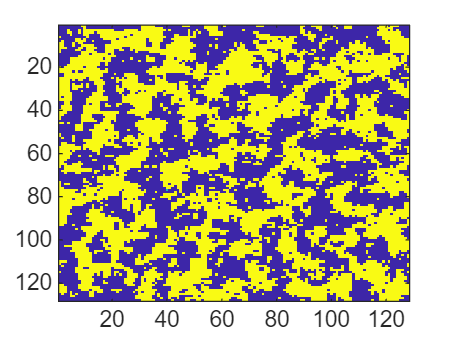

Monte Carlo 步: 4096


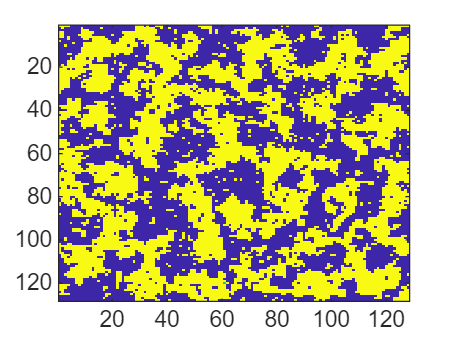

Monte Carlo 步: 8192


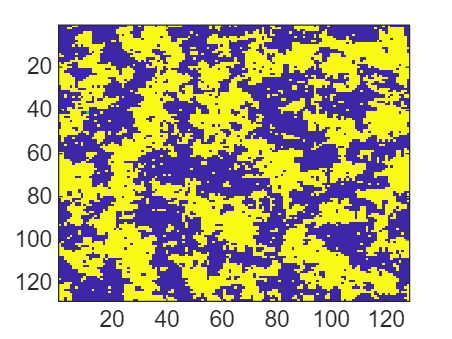

Monte Carlo 步: 16384


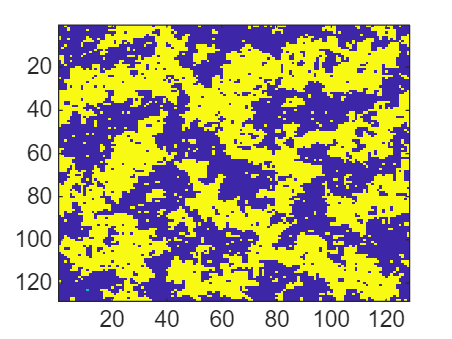

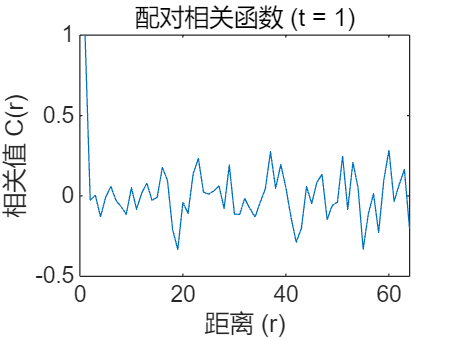

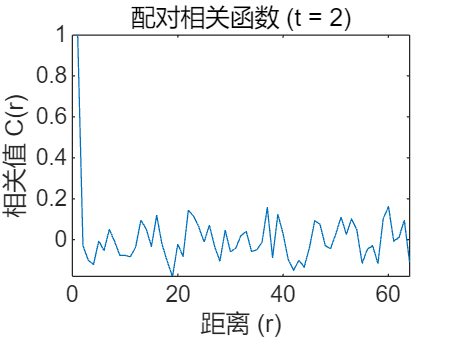

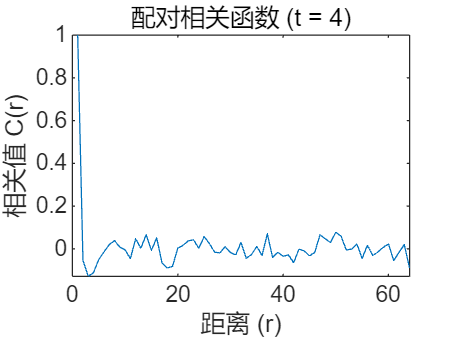

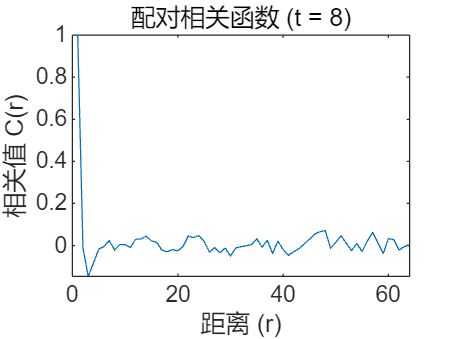

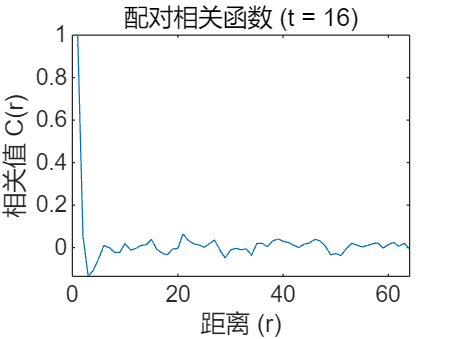

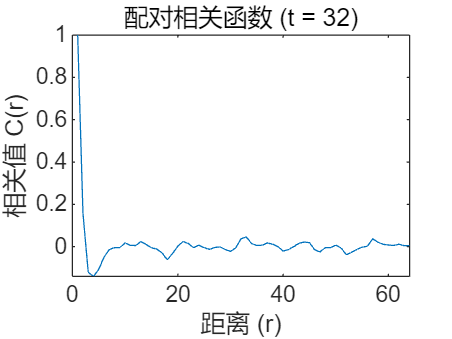

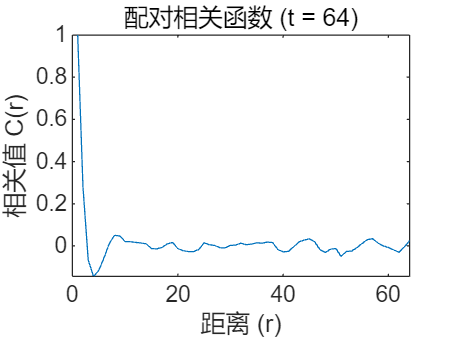

slope: 0.3126  by C(r) Method

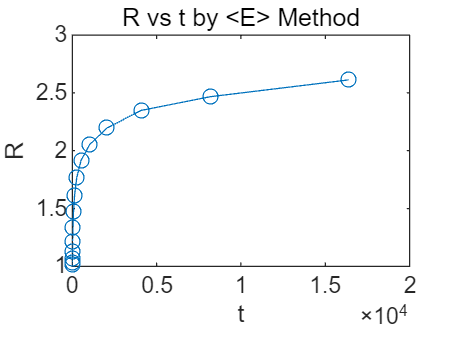

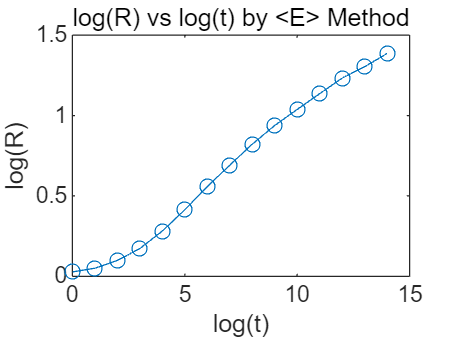

slope: 0.0934  by <E> Method

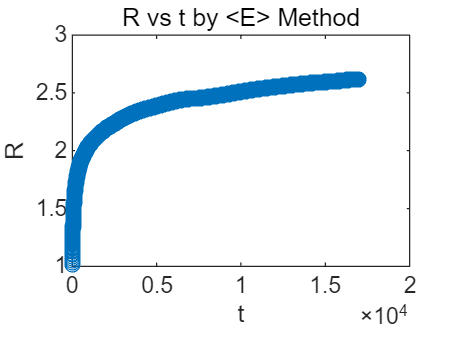

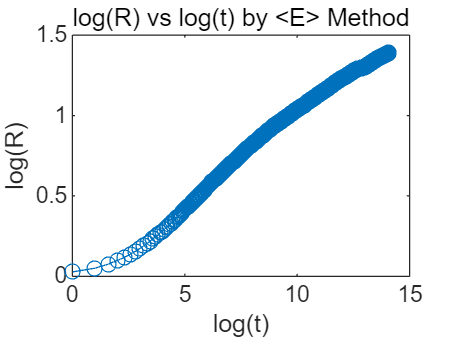

slope: 0.0850  by <E> Method

clear;clc;
binary_alloys_simulation();

function binary_alloys_simulation()
    % 参数设置
    L = 128; % 网格边长
    N = L * L;
    Tc = 2.26; % 临界温度
    factor = 1; % 设置温度与Tc之比
    T = Tc * factor; % 当前温度
    num_A = floor(N / 2);
    num_B = num_A;
    num_mc = 17000; % Monte Carlo 步数(2^15=32768)
    num_steps = L * L; % 每次模拟的步数
    J = 1; % 能量交互系数

    % 生成格子和初始状态
    lattice = createRandomLattice(L, num_A, num_B);
    start_energy = getEnergy(lattice, L, J);
    disp(['初始总能量: ', num2str(start_energy)]);

    % 数据存储
    energies_in_time = [];
    times = [];
    pair_correlation = {};
    R_cross = [];
    time_correlation = [];

    % Monte Carlo 模拟
    [lattice, energies_in_time, times, pair_correlation, R_cross, time_correlation] = ...
        move(lattice, start_energy, J, T, L, num_mc, num_steps);

    % 绘图
    plotCorrelation(pair_correlation, time_correlation);
    plotRFromPairCorrelation(time_correlation,R_cross);

    plotRFromEnergy(times, energies_in_time, L , time_correlation);
end




% 创建值数组并随机打乱
function lattice = createRandomLattice(L, num_A, num_B)
    if(mod(L,2)==0)
        values = [ones(1, num_A), -ones(1, num_B)];
        values(1,randi(L*L))=0;
    elseif(mod(L,2)==1)
        values = [ones(1, num_A), -ones(1, num_B), 0];
    end
    values = values(randperm(numel(values))); % 随机打乱顺序
    lattice = reshape(values, [L, L]); % 转换为 LxL 矩阵
end



% 计算当前网格的总能量
function energy = getEnergy(lattice, L, J)
    energy = 0;
    for i = 1:L
        for j = 1:L
            if lattice(i, j) ~= 0
                neighbors = [lattice(mod(i-2, L)+1, j), lattice(mod(i, L)+1, j), lattice(i, mod(j-2, L)+1), lattice(i, mod(j, L)+1)];
                energy = energy - J * lattice(i, j) * sum(neighbors);
            end
        end
    end
    energy = energy / 2; % 防止双计
end


% Monte Carlo 迭代
function [lattice, energies_in_time, times, pair_correlation, R_cross ,time_correlation] = ...
    move(lattice, start_energy, J, T, L, num_mc, num_steps)
    [vacancy_row, vacancy_col] = find(lattice == 0, 1); % 找到空位
    if (isempty(vacancy_row) || isempty(vacancy_col))
        error('未找到空穴，请检查初始配置');
    end
    vacancy = [vacancy_row, vacancy_col];
    sum_energy = start_energy;

    % 初始化数据存储
    energies_in_time = [];
    times = [];
    pair_correlation = {};
    R_cross = [];
    time_correlation = [];
    %picture_num=1;

    for i = 1:num_mc
        for step = 1:num_steps
            % 随机选择一个移动方向
            dir = randi(4);
            moves = [-1, 0; 1, 0; 0, -1; 0, 1];
            move = moves(dir, :);
            new_vacancy = mod(vacancy + move - 1, L) + 1;

            old_energy = calculateLocalEnergy(lattice, new_vacancy, L, J)*lattice(new_vacancy(1),new_vacancy(2));
            new_energy = calculateLocalEnergy(lattice, vacancy, L, J)*lattice(new_vacancy(1),new_vacancy(2))+J*lattice(new_vacancy(1),new_vacancy(2))^2;
            dE = new_energy - old_energy;

            if (dE <= 0 || rand < exp(-dE / T))
                lattice(vacancy(1), vacancy(2)) = lattice(new_vacancy(1), new_vacancy(2));
                lattice(new_vacancy(1), new_vacancy(2)) = 0;
                vacancy = new_vacancy;
                start_energy = start_energy + dE;
            end
        end

        sum_energy = sum_energy + start_energy;
        energies_in_time(end+1) = sum_energy / (i + 1);
        times(end+1) = i;

        if mod(log2(i), 1) == 0
            disp(['Monte Carlo 步: ', num2str(i)]);
            pair_correlation{end+1} = calculatePairCorrelation(lattice, L);
            temp = calculatePairCorrelation(lattice, L);
            R_cross(end+1) = find(temp(1:end-1) .* temp(2:end) < 0, 1); 
            if isempty(R_cross(end))
                error('配对相关函数法未找到R');
            end
            time_correlation(end+1) = i;

            figure;
            plotLattice(lattice);
        end

        %{
        fig=figure('Visible', 'off');
        if floor(i/100)==i/100
            imagesc(lattice);
            C{picture_num}=frame2im(getframe(fig));
            picture_num=picture_num+1;
            close(fig);
        end
        %}
    end

    %{
    for idx=1:picture_num-1
        [B,map]=rgb2ind(C{idx},256);
        if idx == 1
            imwrite(B,map,'SD_2D.gif','gif', 'Loopcount',inf,'DelayTime',0.05);
        else
            imwrite(B,map,'SD_2D.gif','gif','WriteMode','append','DelayTime',0.05);
        end
    end
    %}
end



% 计算局部能量
function local_energy = calculateLocalEnergy(lattice, pos, L, J)
    neighbors = [lattice(mod(pos(1)-2, L)+1, pos(2)), lattice(mod(pos(1), L)+1, pos(2)), ...
                 lattice(pos(1), mod(pos(2)-2, L)+1), lattice(pos(1), mod(pos(2), L)+1)];
    local_energy = -J *sum(neighbors);
end



% 计算配对相关函数
function pair_correlation = calculatePairCorrelation(lattice, L)
    pair_correlation = zeros(1, L/2);
    for r = 1:L/2
        corr = 0;
        for i = 1:L
            for j = 1:L
                corr = corr + lattice(i, j) * (lattice(mod(i+r-1, L)+1, j)+lattice(i, mod(j+r-1, L)+1)+lattice(mod(i-r-1, L)+1, j)+lattice(i, mod(j-r-1, L)+1));
            end
        end
        pair_correlation(r) = corr/L^2;
    end
    pair_correlation = pair_correlation / pair_correlation(1); % 归一化
end


function plotLattice(lattice)
    % 绘制格点状态
    imagesc(lattice);
end

function plotCorrelation(pair_correlation, time_correlation)
    % 绘制配对相关函数
    for idx = 1:length(pair_correlation)
        figure;
        plot(pair_correlation{idx});
        title(sprintf('配对相关函数 (t = %d)', time_correlation(idx)));
        xlabel('距离 (r)');
        ylabel('相关值 C(r)');
    end
end

function plotRFromPairCorrelation(time_correlation, R_cross)
    % 绘制 R vs t
    figure;
    plot(time_correlation, R_cross, 'o-');
    title('R vs t by C(r) Method');
    xlabel('t');
    ylabel('R');

    % 绘制 log-log 图
    figure;
    plot(log2(time_correlation), log2(R_cross), 'o-');
    title('log(R) vs log(t) by C(r) Method');
    xlabel('log(t)');
    ylabel('log(R)');
    coefficient=polyfit(log2(time_correlation(9:end)),log2(R_cross(9:end)),1);
    fprintf('slope: %.4f  by C(r) Method', coefficient(1));
end




function plotRFromEnergy(times, energies_in_time, L, time_correlation)
    % 从能量绘制关联长度变化
    R = 2 ./ ((energies_in_time / (L^2)) + 2);

    % 绘制 R vs t
    figure;
    plot(time_correlation, R(time_correlation), 'o-');
    title('R vs t by <E> Method');
    xlabel('t');
    ylabel('R');

    % 绘制 log-log 图
    figure;
    plot(log2(time_correlation), log2(R(time_correlation)), 'o-');
    title('log(R) vs log(t) by <E> Method');
    xlabel('log(t)');
    ylabel('log(R)');
    coefficient=polyfit(log2(time_correlation(9:end)),log2(R(time_correlation(9:end))),1);
    fprintf('slope: %.4f  by <E> Method', coefficient(1));



    % 绘制 R vs t
    figure;
    plot(times, R, 'o-');
    title('R vs t by <E> Method');
    xlabel('t');
    ylabel('R');

    % 绘制 log-log 图
    figure;
    plot(log2(times), log2(R), 'o-');
    title('log(R) vs log(t) by <E> Method');
    xlabel('log(t)');
    ylabel('log(R)');
    coefficient=polyfit(log2(times(512:end)),log2(R(512:end)),1);
    fprintf('slope: %.4f  by <E> Method', coefficient(1));
end
